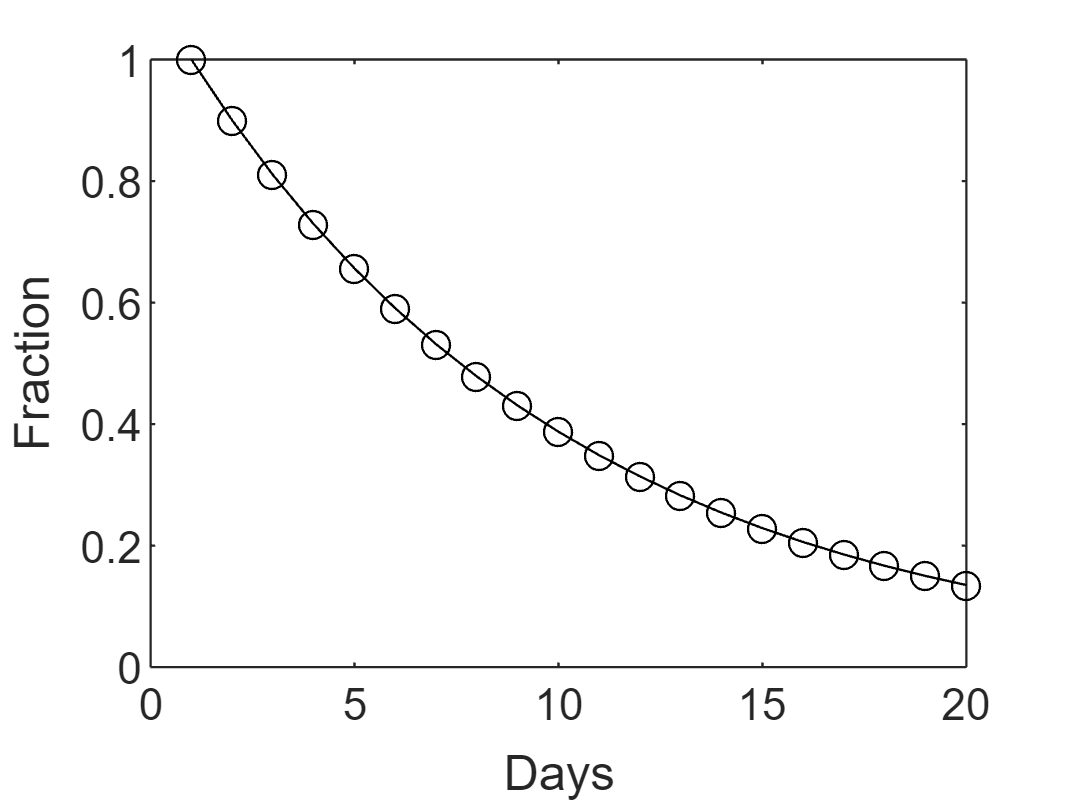

N = 10; % number of scoops in each jar
nMax = 2*N; % max number of days to simulate
x = zeros(1,nMax); % fraction caffenaited
x(1) = 1.0; % initial fraction caffenaited
for n=2:nMax
    x(n)=(1-1/N)*x(n-1);
end
figure;
plot(x,"-ok");
ylabel("Fraction");
xlabel("Days");

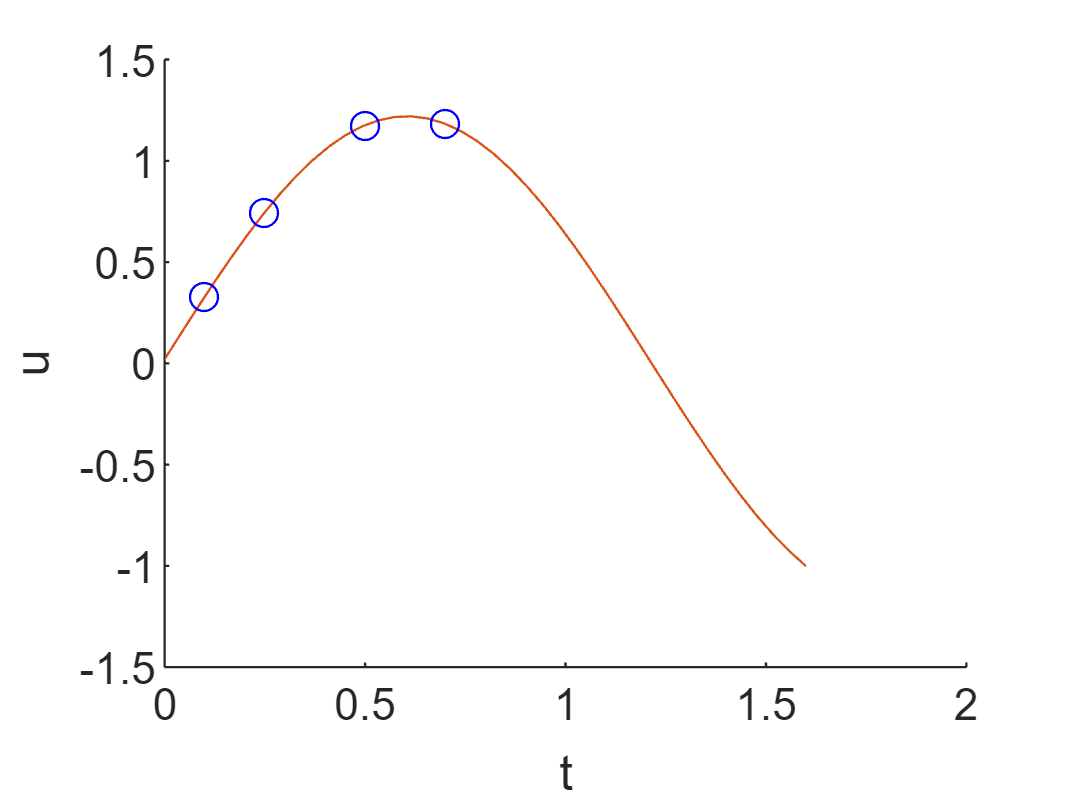

A     = 1.2; % fluorescence intensity units
omega = 2.6; % rad/s
A_0   = 0.02;
u=@(t) A*sin(omega*t)+A_0;
tArray = linspace(0,1.6,40);
uArray = u(tArray);
figure;hold on;
plot(tArray,uArray);
ylabel('u');
xlabel('t');
tArrayCoarse = [0.1 0.25 0.5 0.7];
uArrayCoarse = u(tArrayCoarse);

plot(tArray,uArray);
plot(tArrayCoarse, uArrayCoarse, 'ob')

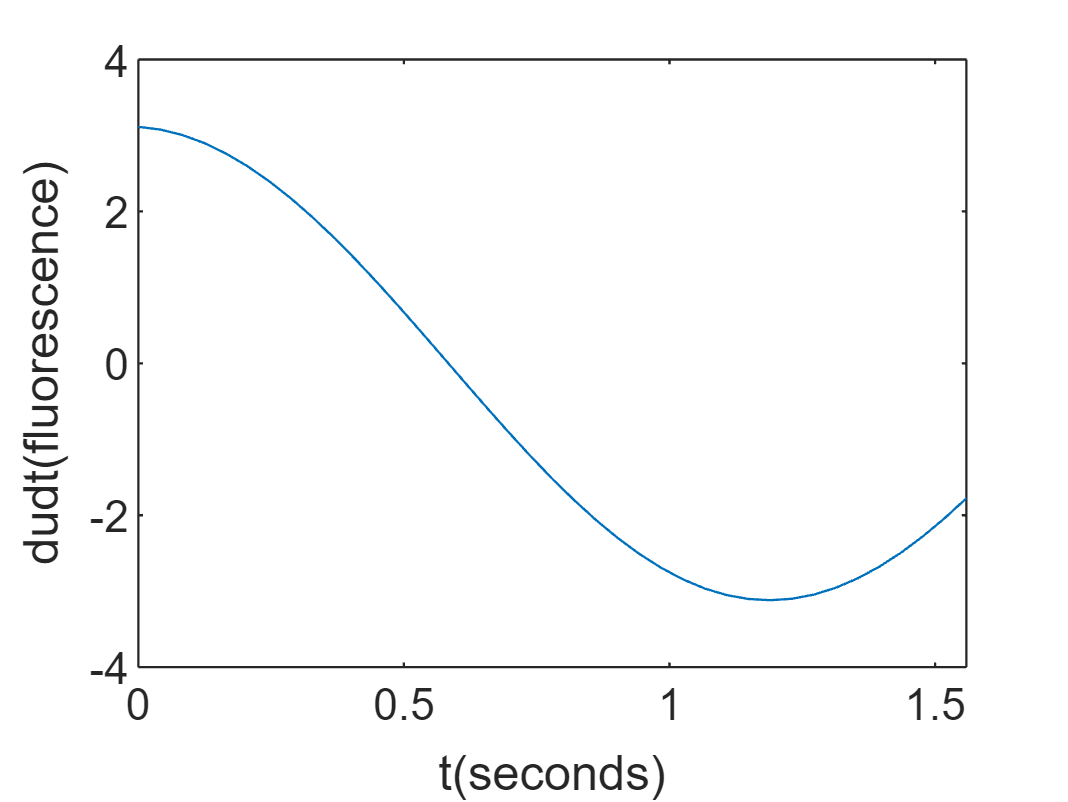

dudt = diff(u(tArray))./diff(tArray);
figure
plot(tArray(1:end-1), dudt);
ylabel("dudt(fluorescence)");
xlabel('t(seconds)');